clear
arm_perm = 320000;
rec_max_A = 3.5; % A/mm2
r0 = 8; % mm
s = 40; % stack
l = 30; % mm
t = 'g'; % g: gird l: latice
V = 24; % Voltage
%x = 0.5; % armature displacement mm
Aw = 0.0503; % mm^2 wire area
Rwm = 350 * 1e-3; % R/m wire resistence
x = 0:0.1:l;

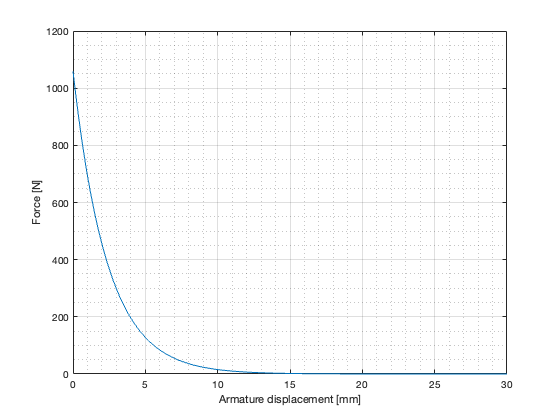

for i=1:length(x)
    [F(i), P, I, N, ra, ro, wLen, Wf, I_safe] = ...
        coil_model(arm_perm, r0, s, l, t, V, x(i), Aw, Rwm);
end
figure()
plot(x,-F)
grid on, grid minor,
xlabel('Armature displacement [mm]'),ylabel('Force [N]')

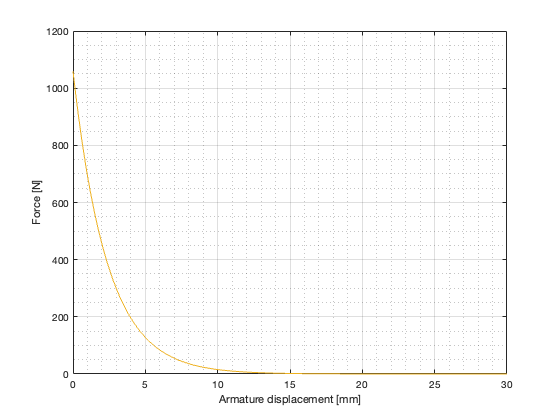

figure()
for j=5:5:50
    for i=1:length(x)
        [F(i), P, I, N, ra, ro, wLen, Wf, I_safe] = ...
            coil_model(arm_perm, r0, j, l, t, V, x(i), Aw, Rwm);
    end
    plot(x,-F)
    hold on
end
hold off
grid on, grid minor,
xlabel('Armature displacement [mm]'),ylabel('Force [N]')

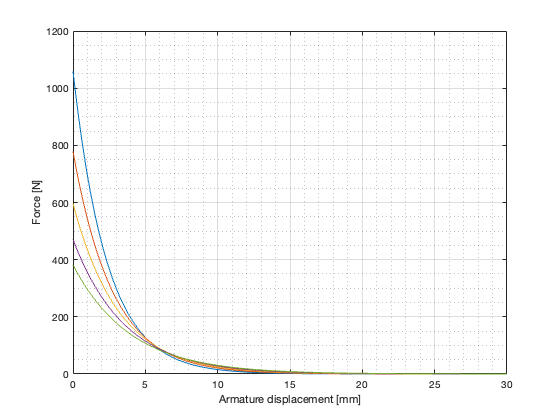

figure()
for j=30:5:50
    for i=1:length(x)
        [F(i), P, I, N, ra, ro, wLen, Wf, I_safe] = ...
            coil_model(arm_perm, r0, s, j, t, V, x(i), Aw, Rwm);
    end
    plot(x,-F)
    hold on
end
hold off
grid on, grid minor,
xlabel('Armature displacement [mm]'),ylabel('Force [N]')